% ----------------------------------------------
% This program formulates the minimimal variance mechanism problem into a
% linear programing problem, and solves it using the built-in solver in Matlab.
% Comments are adquent in the code. 
% If you have any question,
% please feel free to contact Fei Wei at feiwei@nus.edu.sg
% ----------------------------------------------

close all
clear

% eps = 2; % privacy parameter
delta = 0; % privacy parameter
r=0.5; % geometric series constant
axRatio = 3; %the ratio amax/xmax

xmax = 1;
N = 21; % Total number of bins in [-xmax,xmax]
x_bin_size = 1/N;
x_grid = linspace(-xmax+0.5*x_bin_size,xmax-0.5*x_bin_size,N);

% We assign a distribution to X\in x_grid
% In the write-up, this is the data distribution

x_P = ones(1,N)/N; % Uniform distribution

% x_P = x_grid.^2;
% x_P = x_P./ sum(x_P);

% x_P = x_grid-min(x_grid);
% x_P = x_P./sum(x_P);

% figure
% plot(x_grid,x_P,'o',LineWidth=1.5);
% xlabel("x",FontSize=13);
% ylabel("P(x)",FontSize=13);
% grid on

% [totalVariance,pMatrix] = opt_variance(eps,r,axRatio,x_grid,x_P);

% For testing, we sample a sequence of epsilon values
eps_grid = exp(linspace(0,log(8),20));

% The variance of optimal mechanism
VarOpt = zeros(1,length(eps_grid));
VarOptWorst = zeros(1,length(eps_grid));
for i = 1:length(eps_grid)
    [varVector,pMatrix,a_grid] =... 
        opt_variance(eps_grid(i),delta,r,axRatio,x_grid,x_P);
    VarOpt(i) = x_P*varVector;
    VarOptWorst(i) = max(varVector);
end

--------------------------------
eps = 1.000000, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.0535   -0.0800   -0.0278    0.8181    0.2483   -0.1110    0.0497   -0.1227   -0.0833   -0.0468    0.1285


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     1.8981    2.1744    2.2257    2.1319    2.0561    1.9455    2.0561    2.1319    2.2257    2.1744    1.8981


--------------------------------
eps = 1.115658, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.3096    0.1146   -0.0416   -0.2632   -0.0267   -0.1110    0.1151   -0.0473    0.0555   -0.1335   -0.0728


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     1.7745    1.9620    1.9607    1.8537    1.6867    1.7341    1.6867    1.8537    1.9607    1.9620    1.7745


--------------------------------
eps = 1.244693, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.0041    0.0020    0.1110   -0.0751   -0.0392    0.0555    0.0097   -0.0362   -0.5412   -0.0893    0.1267


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     1.5977    1.7101    1.6764    1.5864    1.4740    1.4856    1.4740    1.5864    1.6764    1.7101    1.5977


--------------------------------
eps = 1.388651, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

    0.1011    0.0123    0.0208    0.0076    0.0985    0.0555    0.0052   -0.0173   -0.1943    0.3749    0.0005


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     1.4677    1.5063    1.4444    1.3146    1.2135    1.2197    1.2135    1.3146    1.4444    1.5063    1.4677


--------------------------------
eps = 1.549260, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.1145   -0.0568    0.0416   -0.0330    0.0451         0    0.0693   -0.0279   -0.9298    0.0825   -0.2930


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     1.3028    1.2806    1.1968    1.0501    1.0156    1.0204    1.0156    1.0501    1.1968    1.2806    1.3028


--------------------------------
eps = 1.728444, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.1317    0.0848   -0.0208    0.0199   -0.0156         0   -0.0625   -0.0694   -0.0208   -0.0695    0.1489


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     1.1399    1.0651    0.9617    0.8815    0.8284    0.8151    0.8284    0.8815    0.9617    1.0651    1.1399


--------------------------------
eps = 1.928352, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.2016    0.0505    0.0971   -0.0893   -0.0536   -0.4441   -0.0618   -0.0126    0.1041   -0.0505   -0.1634


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.9760    0.8643    0.7479    0.7183    0.6599    0.6171    0.6599    0.7183    0.7479    0.8643    0.9760


--------------------------------
eps = 2.151381, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

    0.3201    0.0394    0.0243   -0.8553    0.0518    0.0833   -0.0008   -0.0016   -0.0139   -0.0273    0.0112


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.8156    0.6842    0.6032    0.5608    0.5262    0.4482    0.5262    0.5608    0.6032    0.6842    0.8156


--------------------------------
eps = 2.400205, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-14 *

   -0.0852   -0.0024    0.0028   -0.0327   -0.0008         0   -0.0013   -0.0050   -0.0045    0.0048    0.2937


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.6356    0.4980    0.4893    0.4531    0.4161    0.3372    0.4161    0.4531    0.4893    0.4980    0.6356


--------------------------------
eps = 2.677808, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

    0.0353    0.0210    0.0971   -0.0133   -0.0474         0   -0.0890   -0.0115   -0.3435   -0.0253    0.0397


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.5587    0.3787    0.3498    0.3283    0.2907    0.2897    0.2907    0.3283    0.3498    0.3787    0.5587


--------------------------------
eps = 2.987518, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

    0.4397    0.7291   -0.2586    0.2455    0.2092         0    0.1766    0.0389   -0.2376    0.5267    0.2103


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.3783    0.3383    0.2983    0.2311    0.1883    0.1835    0.1883    0.2311    0.2983    0.3383    0.3783


--------------------------------
eps = 3.333048, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.0697   -0.0207    0.0369   -0.0149    0.0020         0    0.0113    0.0115    0.1506   -0.0191    0.0595


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.2824    0.2424    0.2024    0.1624    0.1380    0.1313    0.1380    0.1624    0.2024    0.2424    0.2824


--------------------------------
eps = 3.718541, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

    0.5471    0.0950   -0.2528    0.1438   -0.1362         0    0.0125    0.0794    0.1464   -0.3765   -0.0320


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.1882    0.1882    0.1559    0.1079    0.0918    0.0918    0.0918    0.1079    0.1559    0.1882    0.1882


--------------------------------
eps = 4.148620, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

   -0.0015    0.1966   -0.1278    0.0502    0.0027         0   -0.1644    0.0483    0.0182   -0.1161   -0.0768


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.1219    0.1219    0.1186    0.0758    0.0677    0.0677    0.0677    0.0758    0.1186    0.1219    0.1219


--------------------------------
eps = 4.628441, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

    0.1549   -0.0273    0.0859   -0.0590    0.0737    0.2776    0.0312    0.0988    0.0364    0.1127    0.0849


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.0959    0.0802    0.0678    0.0596    0.0541    0.0541    0.0541    0.0596    0.0678    0.0802    0.0959


--------------------------------
eps = 5.163757, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

    0.3070   -0.0510   -0.0181    0.0151    0.0137    0.0173    0.0296    0.0086    0.0873    0.0230    0.1841


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.0758    0.0814    0.0414    0.0300    0.0224    0.0186    0.0224    0.0300    0.0414    0.0814    0.0758


--------------------------------
eps = 5.760986, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-17 *

   -0.2643   -0.4375    0.2884    0.1712    0.2330         0    0.0476   -0.1346   -0.3927   -0.2279   -0.5836


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans = 1×11
    0.0511    0.0384    0.0283    0.0207    0.0156    0.0131    0.0156    0.0207    0.0283    0.0384    0.0511


--------------------------------
eps = 6.427290, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1×11
1.0e-17 *

   -0.5578   -0.0388   -0.3448   -0.0803   -0.0612   -0.0867   -0.0945   -0.0116   -0.0561    0.0674   -0.0638


Distribution validity check (should be all ones):


ans = 1×11
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans = 1×11
    0.0273    0.0205    0.0150    0.0110    0.0083    0.0069    0.0083    0.0110    0.0150    0.0205    0.0273


--------------------------------
eps = 7.170657, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1×11
1.0e-17 *

    0.2087    0.1209    0.0358   -0.0323   -0.0065         0    0.0421    0.0405    0.0721   -0.0712    0.1772


Distribution validity check (should be all ones):


ans = 1×11
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans = 1×11
    0.0133    0.0099    0.0073    0.0053    0.0040    0.0033    0.0040    0.0053    0.0073    0.0099    0.0133


--------------------------------
eps = 8.000000, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1×11
1.0e-18 *

   -0.5645    0.2822   -0.5858   -0.1598    0.1670   -0.2168   -0.1730    0.0463   -0.3867    0.1037    0.1586


Distribution validity check (should be all ones):


ans = 1×11
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans = 1×11
    0.0059    0.0044    0.0032    0.0023    0.0018    0.0015    0.0018    0.0023    0.0032    0.0044    0.0059


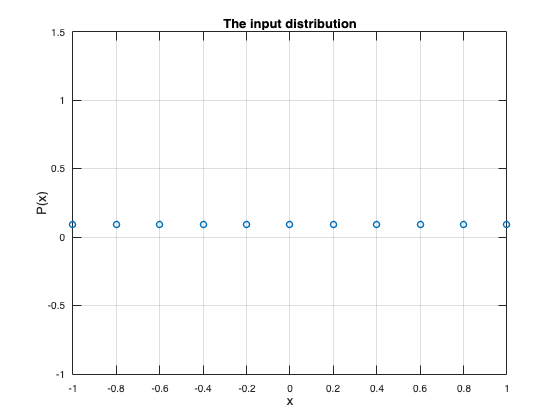

% The variance vector of Laplace mechanism
VarLaplace = zeros(1,length(eps_grid));
for i = 1:length(eps_grid)
    VarLaplace(i) = 8/(eps_grid(i))^2;
end

% The variance vector of Duchi mechanism
VarDuchi = zeros(1,length(eps_grid));
VarDuchiWorst = zeros(1,length(eps_grid));
var_duchi = @(ti,eps) ((exp(eps)+1)/(exp(eps)-1)).^2 - ti.^2;
for i = 1:length(eps_grid)
    temp = var_duchi(x_grid,eps_grid(i));
    VarDuchi(i) = temp *x_P';
    VarDuchiWorst(i) = max(temp);
end

% The variance vector of piece-wise mechanism
VarPiecewise = zeros(1,length(eps_grid));
VarPiecewiseWorst = zeros(1,length(eps_grid));
var_piecewise = @(ti,eps) ti.^2./(exp(eps/2)-1) + (exp(eps/2)+3)/3/(exp(eps/2)-1)^2;
for i = 1:length(eps_grid)
    temp = var_piecewise(x_grid,eps_grid(i));
    VarPiecewise(i) = temp *x_P';
    VarPiecewiseWorst(i) = max(temp);
end

% The variance vector of Hybrid mechanism
VarHybrid = zeros(1,length(eps_grid));
VarHybridWorst = zeros(1,length(eps_grid));
alpha = @(eps) sign(max(eps-0.61,0))*(1-exp(-eps/2));
var_hybrid = @(ti,eps) alpha(eps)*var_piecewise(ti,eps) + (1-alpha(eps))*var_duchi(ti,eps);
for i = 1:length(eps_grid)
    temp = var_hybrid(x_grid,eps_grid(i));
    VarHybrid(i) = temp *x_P';
    VarHybridWorst(i) = max(temp);
end

% The plots

figure;
plot(x_grid,x_P,'o',LineWidth=1.5);
title("The input distribution",FontSize=13);
xlabel("x",FontSize=13);
ylabel("P(x)",FontSize=13);
grid on

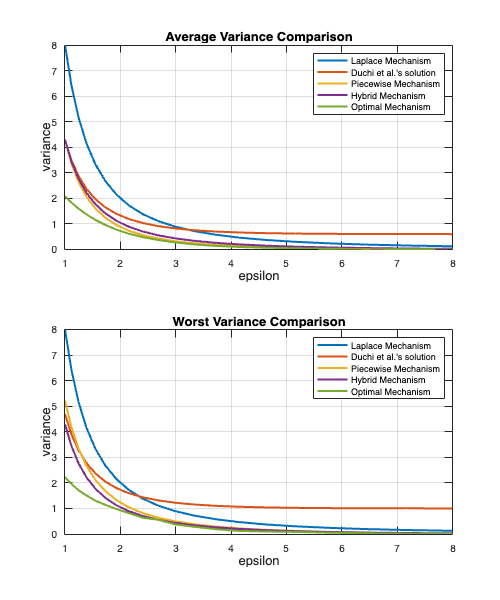


figure;
f = figure;
f.Position = [0 0 500 600];

subplot(2,1,1)
plot(eps_grid,VarLaplace,LineWidth=2);
hold on
plot(eps_grid,VarDuchi,LineWidth=2);
hold on
plot(eps_grid,VarPiecewise,LineWidth=2);
hold on
plot(eps_grid,VarHybrid,LineWidth=2);
hold on
plot(eps_grid,VarOpt,LineWidth=2);

title("Average Variance Comparison",FontSize=13)
xlabel("epsilon",FontSize=13)
ylabel("variance",FontSize=13)
legend("Laplace Mechanism", "Duchi et al.'s solution",...
    "Piecewise Mechanism","Hybrid Mechanism","Optimal Mechanism")
grid on

subplot(2,1,2)
plot(eps_grid,VarLaplace,LineWidth=2);
hold on
plot(eps_grid,VarDuchiWorst,LineWidth=2);
hold on
plot(eps_grid,VarPiecewiseWorst,LineWidth=2);
hold on
plot(eps_grid,VarHybridWorst,LineWidth=2);
hold on
plot(eps_grid,VarOptWorst,LineWidth=2);
title("Worst Variance Comparison",FontSize=13)
xlabel("epsilon",FontSize=13)
ylabel("variance",FontSize=13)
legend("Laplace Mechanism", "Duchi et al.'s solution",...
    "Piecewise Mechanism","Hybrid Mechanism","Optimal Mechanism")
grid on

q = 10; % quantization level
% eps = 2; % privacy parameter
delta = 0; % privacy parameter
r=0.5; % geometric series constant
axRatio = 4; %the ratio amax/xmax
eps = 2; % the privacy parameter

xmax = 1;
xmax = floor(xmax*q)/q; % We need to make sure they are integers
M = 2*xmax*q+1; % total amount of x samples
x_grid = linspace(-xmax,xmax,M);

% We assign a distribution to X\in x_grid

x_P = ones(1,M)/M; % Uniform distribution

% x_P = x_grid.^2;
% x_P = x_P./ sum(x_P);

% x_P = x_grid-min(x_grid);
% x_P = x_P./sum(x_P);

[varVector,pMatrix,a_grid] =...
    opt_variance(eps,delta,r,axRatio,x_grid,x_P);

--------------------------------
eps = 2.000000, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-14 *

   -0.0441   -0.0290    0.0057    0.0073   -0.0051   -0.1915    0.0008   -0.0007   -0.1023    0.0031   -0.0278   -0.0051    0.0073    0.0014   -0.0122    0.0736    0.0003    0.0026    0.0016    0.0268   -0.0077


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     1.0336    0.8948    0.8684    0.8367    0.8026    0.7674    0.7382    0.7061    0.6662    0.6263    0.5983    0.6263    0.6662    0.7061    0.7382    0.7674    0.8026    0.8367    0.8684    0.8948    1.0336


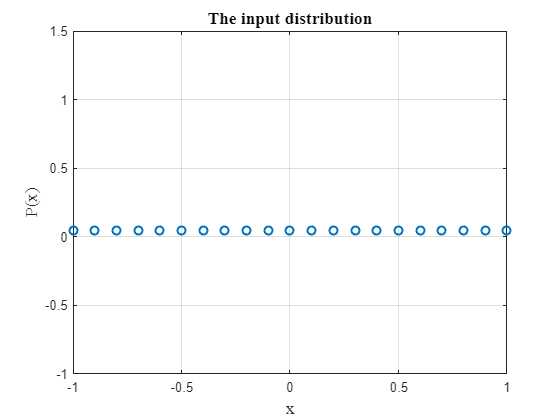

% The plots

figure;
plot(x_grid,x_P,'o',LineWidth=1.5);
title("The input distribution",'FontSize',13,'FontName','Times');
xlabel("x",'FontSize',13,'FontName','Times');
ylabel("P(x)",'FontSize',13,'FontName','Times');
grid on

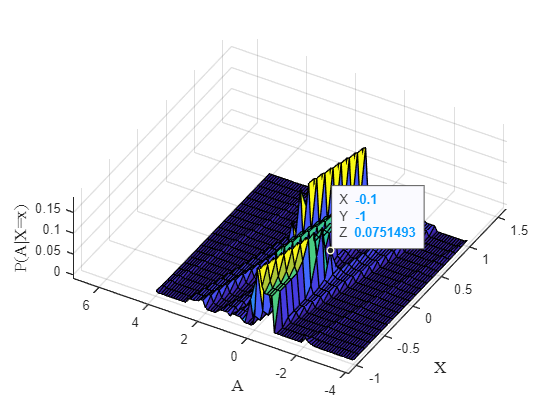


figure
[X_grid,Y_grid] = meshgrid(-x_grid,a_grid);
surf(X_grid,Y_grid,pMatrix');
xlabel("X",'FontSize',13,'FontName','Times');
ylabel("A",'FontSize',13,'FontName','Times');
zlabel("P(A|X=x)",'FontSize',13,'FontName','Times');